# Sample 2-4

## 画像データの入出力

ヒストグラム均等化 

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Input and output of images

Histogram equalization

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 処理画像の準備

(Preparation of sample image)

本サンプルで利用する画像データを収めたdata フォルダにパスをとおす。

Create a path to the data folder that contains images used in this sample.

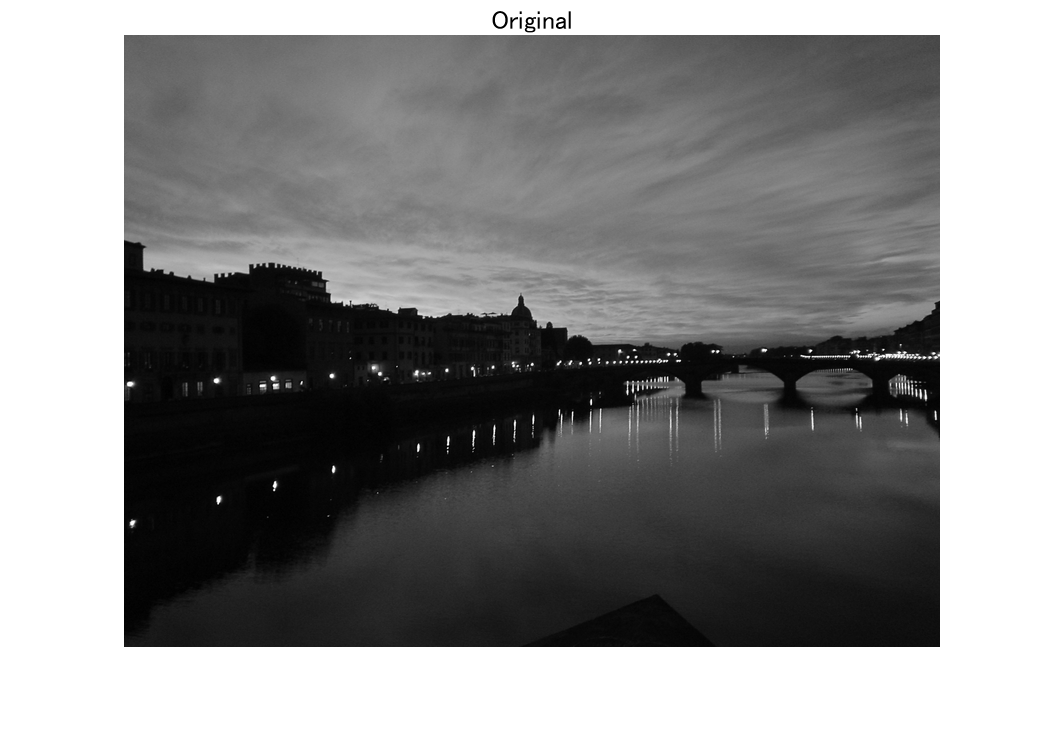

addpath('./data')
close
% Reading original image
I = im2double(rgb2gray(imread('firenzeRgb.jpg')));
imshow(I)
title('Original')

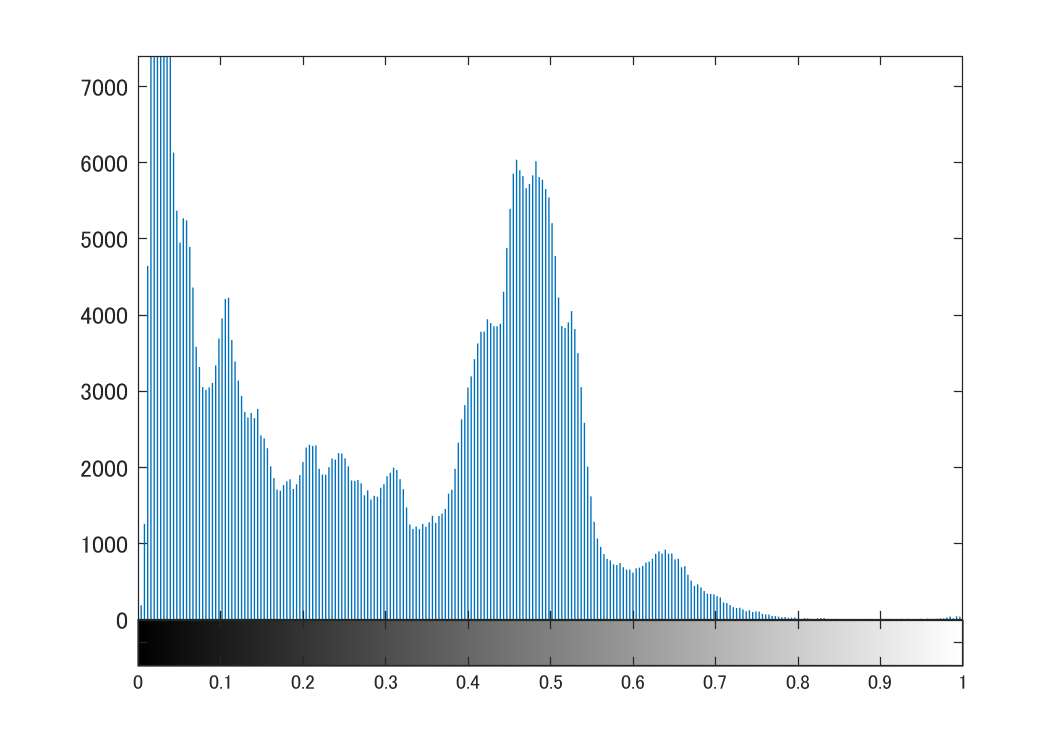

imhist(I)

### ヒストグラム均等化前の加工

(Process before histogram equalization)


$$v=T_1(x)= x^\gamma $$



$$y=T_2(v)= \frac{1}{2}(\mathrm{sign}(2v-1)|2v-1|^{10^{-\alpha}}+1)$$


% Definition of process
gamma = 1

gamma = 1

alpha = 0

alpha = 0

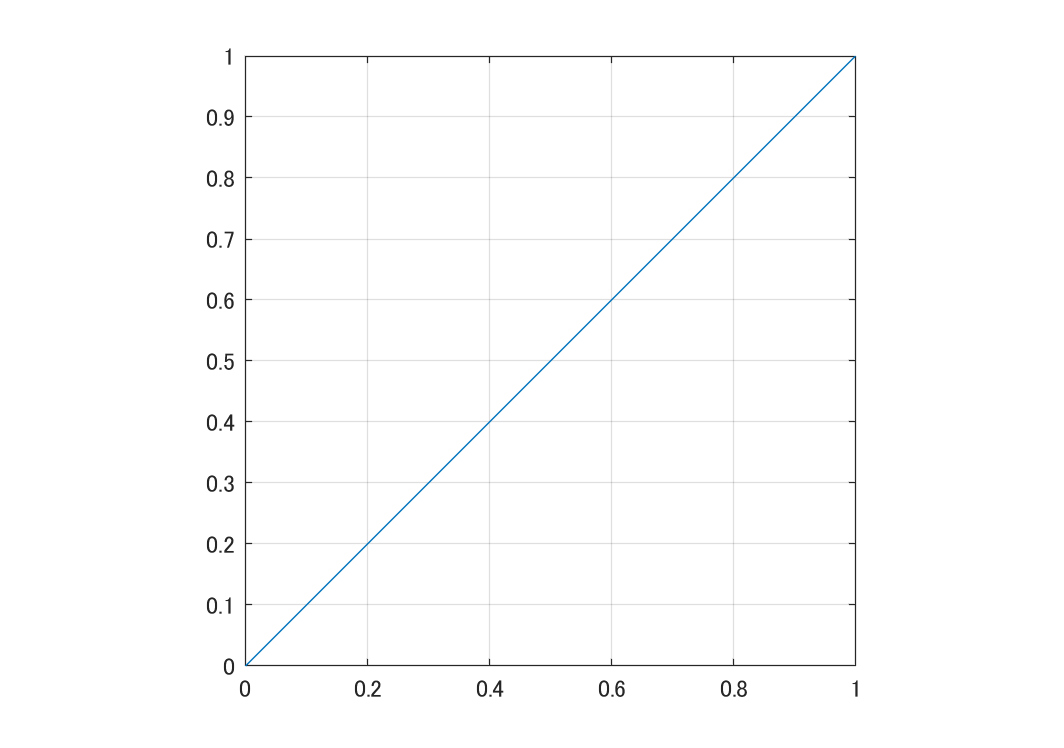

T1 = @(x) x.^gamma;
T2 = @(v) 0.5*(sign(2.0*v-1.0).*abs(2*v-1.0).^(10^(-alpha))+1.0);
Tp = @(x) T2(T1(x));
fplot(Tp,[0,1])
axis square
grid on

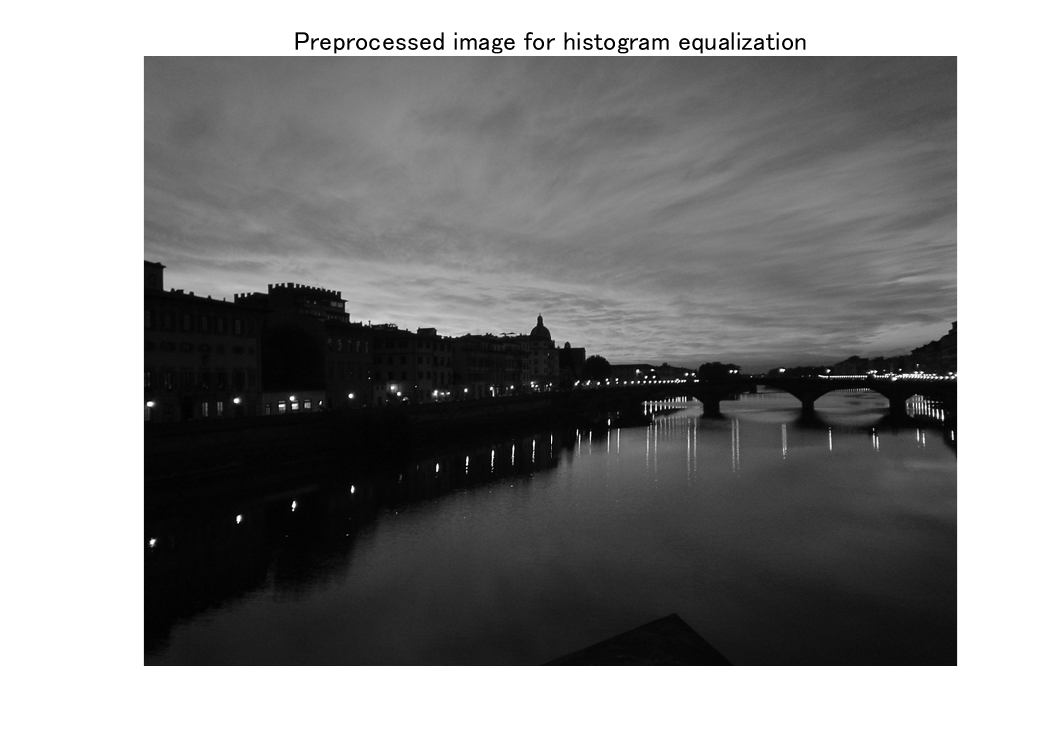

% Preprocessing for histogram equalization
J = Tp(I);
imshow(J)
title('Preprocessed image for histogram equalization')

imhist(J)

### ヒストグラム均等化

(Histgram equalization)

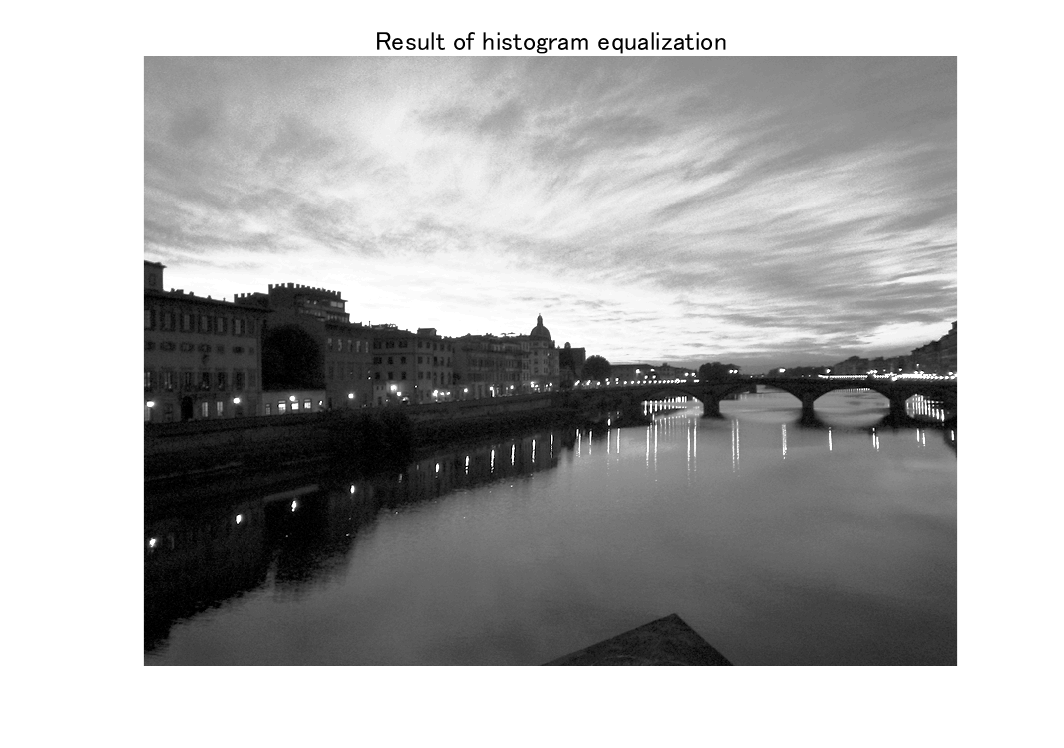

% Power law conversion with IMADUST function
K = histeq(J);
imshow(K)
title('Result of histogram equalization')

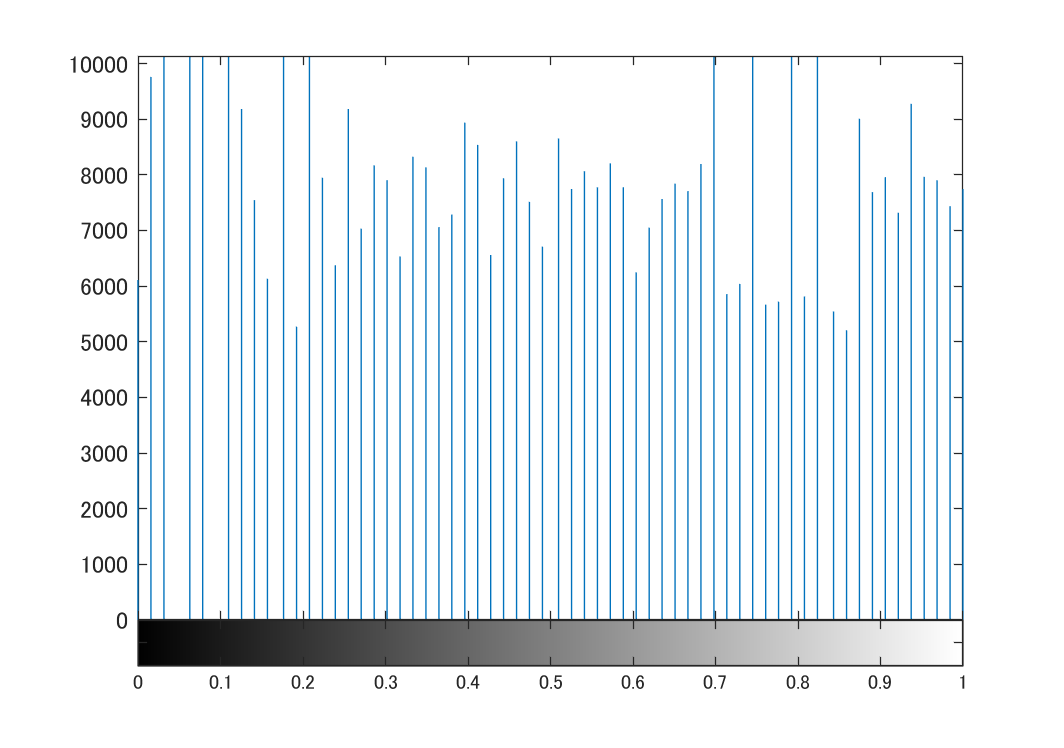

imhist(K)

© Copyright, Shogo MURAMATSU, All rights reserved.